# Compare to MFEVAL

clear

## Compare FY0

folder = fileparts(matlab.desktop.editor.getActiveFilename());
fileMeasurement = fullfile(folder, 'ttc/cornering.mat');
fileTIR = fullfile(folder, 'ttc/obfuscated.tir');

parser = tydex.parsers.FSAETTC_SI_ISO_Mat();
measurements = parser.run(fileMeasurement);
measurement = measurements(34);
[SX,SA,FZ,IP,IA,VX,FX,FY,MZ,MY,MX,W,T] = unpack(measurement);

tyre = MagicFormulaTyre(fileTIR);
[~,FY_mdl] = magicformula(tyre,SX,SA,FZ,IP,IA,VX);

sz = size(SA);
inputs = zeros(length(SA), 7);
inputs(:,1) = ones(sz)*FZ; % vertical load
inputs(:,2) = ones(sz).*SX; % slip ratio
inputs(:,3) = SA; % slip angle
inputs(:,4) = ones(sz)*IA; % inclination angle
inputs(:,5) = zeros(sz); % turn slip
inputs(:,6) = VX; % forward speed
inputs(:,7) = ones(sz)*IP; % pressure
outMF = mfeval(fileTIR, inputs, 221);

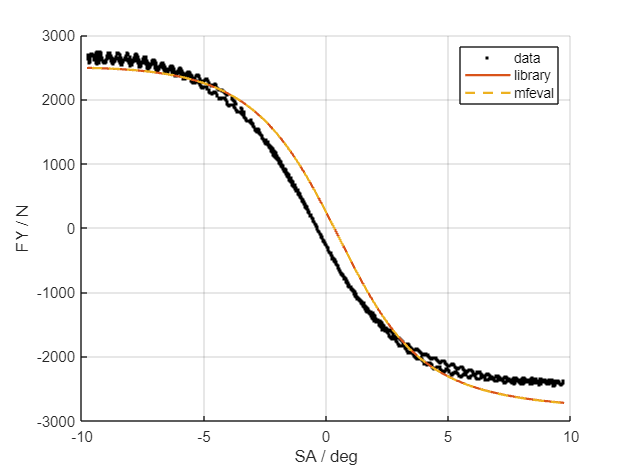

FY_mfeval = outMF(:,2);

r2d = @rad2deg;
figure(); hold on; grid on
plot(r2d(SA), FY, 'k.')
plot(r2d(SA), FY_mdl, 'LineWidth', 1.5)
plot(r2d(SA), FY_mfeval, '--', 'LineWidth', 1.5)
legend data library mfeval
ylabel('FY / N'); xlabel('SA / deg')

## Compare FX

folder = fileparts(matlab.desktop.editor.getActiveFilename());
fileMeasurement = fullfile(folder, 'ttc/drivebrake.mat');
fileTIR = fullfile(folder, 'ttc/obfuscated.tir');

parser = tydex.parsers.FSAETTC_SI_ISO_Mat();
measurements = parser.run(fileMeasurement);
measurement = measurements(91);

[SX,SA,FZ,IP,IA,VX,FX,FY,MZ,MY,MX,W,T] = unpack(measurement);

tyre = MagicFormulaTyre(fileTIR);
FX_mdl = magicformula(tyre,SX,SA,FZ,IP,IA,VX);

sz = size(SX);
inputs = zeros(length(SX), 7);
inputs(:,1) = ones(sz)*FZ; % vertical load
inputs(:,2) = ones(sz).*SX; % slip ratio
inputs(:,3) = SA; % slip angle
inputs(:,4) = ones(sz)*IA; % inclination angle
inputs(:,5) = zeros(sz); % turn slip
inputs(:,6) = VX; % forward speed
inputs(:,7) = ones(sz)*IP; % pressure
outMF = mfeval(fileTIR, inputs, 221);

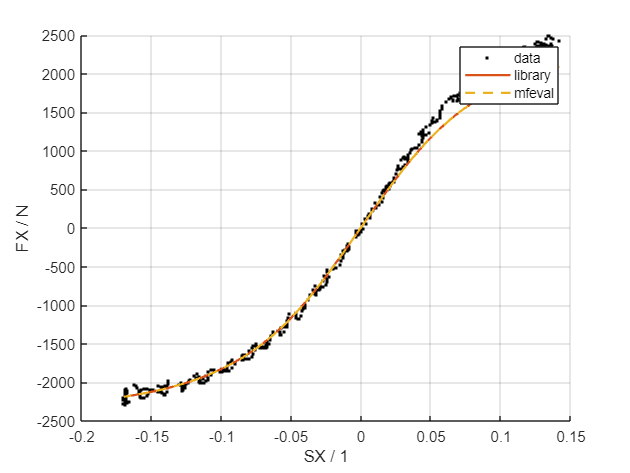

FX_mfeval = outMF(:,1);

figure(); hold on; grid on
plot(SX, FX, 'k.')
plot(SX, FX_mdl, 'LineWidth', 1.5)
plot(SX, FX_mfeval, '--', 'LineWidth', 1.5)
legend data library mfeval
ylabel('FX / N'); xlabel('SX / 1')

## Compare FY

folder = fileparts(matlab.desktop.editor.getActiveFilename());
fileMeasurement = fullfile(folder, 'ttc/drivebrake.mat');
fileTIR = fullfile(folder, 'ttc/obfuscated.tir');

parser = tydex.parsers.FSAETTC_SI_ISO_Mat();
measurements = parser.run(fileMeasurement);
measurement = measurements(104);

[SX,SA,FZ,IP,IA,VX,FX,FY,MZ,MY,MX,W,T] = unpack(measurement);

tyre = MagicFormulaTyre(fileTIR);
[~,FY_mdl] = magicformula(tyre,SX,SA,FZ,IP,IA,VX);

sz = size(SX);
inputs = zeros(length(SX), 7);
inputs(:,1) = ones(sz)*FZ; % vertical load
inputs(:,2) = ones(sz).*SX; % slip ratio
inputs(:,3) = SA; % slip angle
inputs(:,4) = ones(sz)*IA; % inclination angle
inputs(:,5) = zeros(sz); % turn slip
inputs(:,6) = VX; % forward speed
inputs(:,7) = ones(sz)*IP; % pressure
outMF = mfeval(fileTIR, inputs, 221);

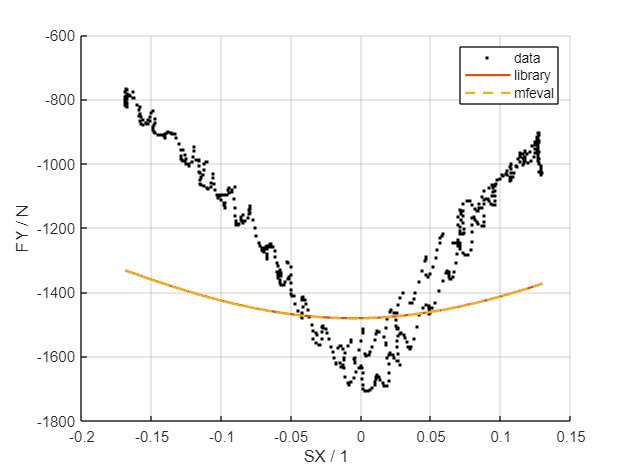

FY_mfeval = outMF(:,2);

figure(); hold on; grid on
plot(SX, FY, 'k.')
plot(SX, FY_mdl, 'LineWidth', 1.5)
plot(SX, FY_mfeval, '--', 'LineWidth', 1.5)
legend data library mfeval
ylabel('FY / N'); xlabel('SX / 1')

## Compare FX

folder = fileparts(matlab.desktop.editor.getActiveFilename());
fileMeasurement = fullfile(folder, 'ttc/drivebrake.mat');
fileTIR = fullfile(folder, 'ttc/obfuscated.tir');

parser = tydex.parsers.FSAETTC_SI_ISO_Mat();
measurements = parser.run(fileMeasurement);
measurement = measurements(104);

[SX,SA,FZ,IP,IA,VX,FX,FY,MZ,MY,MX,W,T] = unpack(measurement);

tyre = MagicFormulaTyre(fileTIR);
FX_mdl = magicformula(tyre,SX,SA,FZ,IP,IA,VX);

sz = size(SX);
inputs = zeros(length(SX), 7);
inputs(:,1) = ones(sz)*FZ; % vertical load
inputs(:,2) = ones(sz).*SX; % slip ratio
inputs(:,3) = SA; % slip angle
inputs(:,4) = ones(sz)*IA; % inclination angle
inputs(:,5) = zeros(sz); % turn slip
inputs(:,6) = VX; % forward speed
inputs(:,7) = ones(sz)*IP; % pressure
outMF = mfeval(fileTIR, inputs, 221);

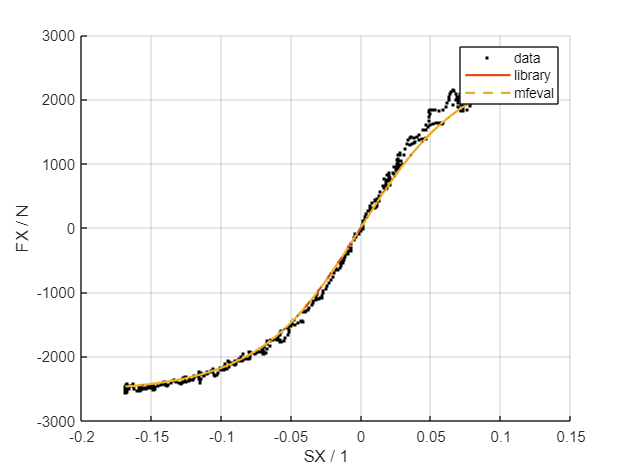

FX_mfeval = outMF(:,1);

figure(); hold on; grid on
plot(SX, FX, 'k.')
plot(SX, FX_mdl, 'LineWidth', 1.5)
plot(SX, FX_mfeval, '--', 'LineWidth', 1.5)
legend data library mfeval
ylabel('FX / N'); xlabel('SX / 1')

## Compare MZ (Pure Slip)

folder = fileparts(matlab.desktop.editor.getActiveFilename());
fileMeasurement = fullfile(folder, 'ttc/cornering.mat');
fileTIR = fullfile(folder, 'ttc/obfuscated.tir');

parser = tydex.parsers.FSAETTC_SI_ISO_Mat();
measurements = parser.run(fileMeasurement);
measurement = measurements(42);
[SX,SA,FZ,IP,IA,VX,FX,FY,MZ,MY,MX,W,T] = unpack(measurement);

tyre = MagicFormulaTyre(fileTIR);
[~,~,MZ_mdl] = magicformula(tyre,SX,SA,FZ,IP,IA,VX);

sz = size(SA);
inputs = zeros(numel(SA), 7);
inputs(:,1) = ones(sz)*FZ; % vertical load
inputs(:,2) = ones(sz).*SX; % slip ratio
inputs(:,3) = SA; % slip angle
inputs(:,4) = ones(sz)*IA; % inclination angle
inputs(:,5) = zeros(sz); % turn slip
inputs(:,6) = VX; % forward speed
inputs(:,7) = ones(sz)*IP; % pressure
outMF = mfeval(fileTIR, inputs, 221);

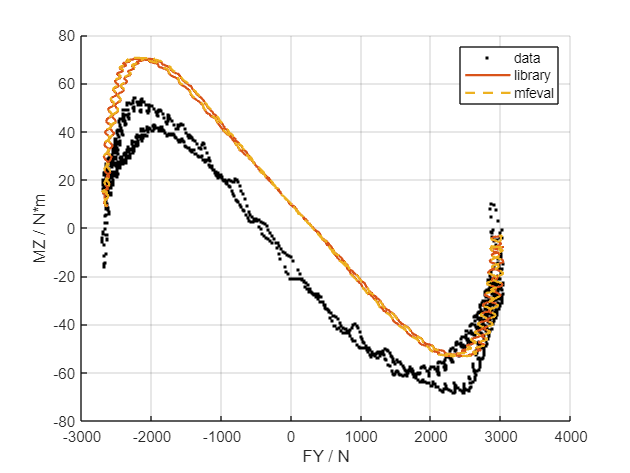

MZ_mfeval = outMF(:,6);

figure(); hold on; grid on
plot(FY, MZ, 'k.')
plot(FY, MZ_mdl, 'LineWidth', 1.5)
plot(FY, MZ_mfeval, '--', 'LineWidth', 1.5)
legend data library mfeval
ylabel('MZ / N*m'); xlabel('FY / N')

## Compare MZ (Combined Slip)

folder = fileparts(matlab.desktop.editor.getActiveFilename());
fileMeasurement = fullfile(folder, 'ttc/drivebrake.mat');
fileTIR = fullfile(folder, 'ttc/obfuscated.tir');

parser = tydex.parsers.FSAETTC_SI_ISO_Mat();
measurements = parser.run(fileMeasurement);
measurement = measurements(91);
[SX,SA,FZ,IP,IA,VX,FX,FY,MZ,MY,MX,W,T] = unpack(measurement);

tyre = MagicFormulaTyre(fileTIR);
[~,~,MZ_mdl] = magicformula(tyre,SX,SA,FZ,IP,IA,VX);

sz = size(SX);
inputs = zeros(numel(SX), 7);
inputs(:,1) = ones(sz)*FZ; % vertical load
inputs(:,2) = ones(sz).*SX; % slip ratio
inputs(:,3) = SA; % slip angle
inputs(:,4) = ones(sz)*IA; % inclination angle
inputs(:,5) = zeros(sz); % turn slip
inputs(:,6) = VX; % forward speed
inputs(:,7) = ones(sz)*IP; % pressure
outMF = mfeval(fileTIR, inputs, 221);

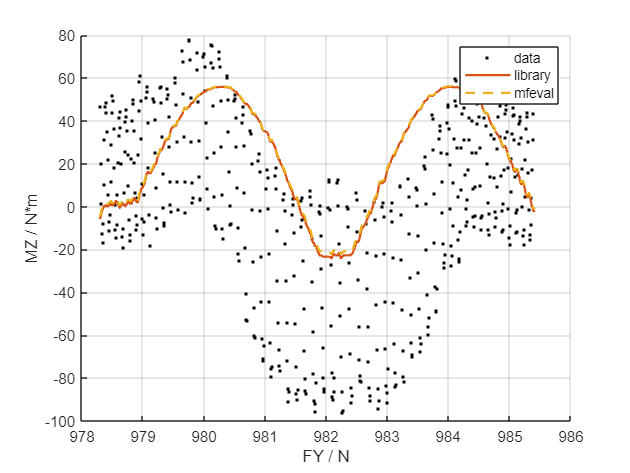

MZ_mfeval = outMF(:,6);

figure(); hold on; grid on
plot(T, MZ, 'k.')
plot(T, MZ_mdl, 'LineWidth', 1.5)
plot(T, MZ_mfeval, '--', 'LineWidth', 1.5)
legend data library mfeval
ylabel('MZ / N*m'); xlabel('FY / N')

## Compare MY

folder = fileparts(matlab.desktop.editor.getActiveFilename());
fileMeasurement = fullfile(folder, 'ttc/cornering.mat');
fileTIR = fullfile(folder, 'ttc/obfuscated.tir');

parser = tydex.parsers.FSAETTC_SI_ISO_Mat();
measurements = parser.run(fileMeasurement);
measurement = measurements(42);
[SX,SA,FZ,IP,IA,VX,FX,FY,MZ,MY,MX,W,T] = unpack(measurement);

tyre = MagicFormulaTyre(fileTIR);
[~,~,~,MY_mdl] = magicformula(tyre,SX,SA,FZ,IP,IA,VX);

sz = size(SA);
inputs = zeros(numel(SA), 7);
inputs(:,1) = ones(sz)*FZ; % vertical load
inputs(:,2) = ones(sz).*SX; % slip ratio
inputs(:,3) = SA; % slip angle
inputs(:,4) = ones(sz)*IA; % inclination angle
inputs(:,5) = zeros(sz); % turn slip
inputs(:,6) = VX; % forward speed
inputs(:,7) = ones(sz)*IP; % pressure
outMF = mfeval(fileTIR, inputs, 221);

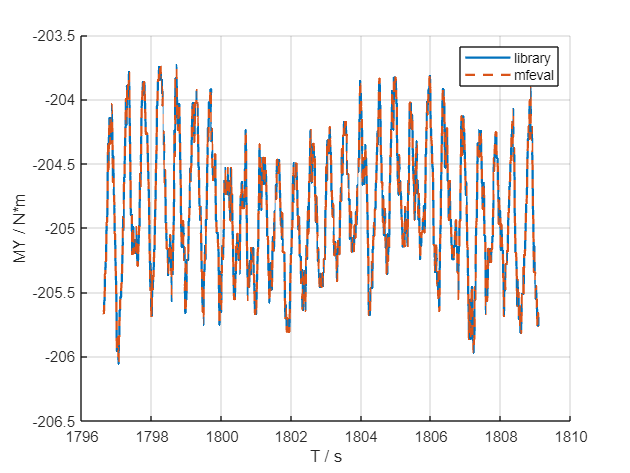

MY_mfeval = outMF(:,5);

r2d = @rad2deg;
figure(); hold on; grid on
plot(T, MY_mdl, 'LineWidth', 1.5)
plot(T, MY_mfeval, '--', 'LineWidth', 1.5)
legend library mfeval
ylabel('MY / N*m'); xlabel('T / s')

**Note**: MFEVAL uses Fz0 instead of Fz to calculate rolling moment. This does not make sense to me, because higher loads will result in higher rolling resistance. Perhaps this is covered by the influence of parameters such as `QSY6` but I kept the definition of Pacejka's book.

## Compare MX

folder = fileparts(matlab.desktop.editor.getActiveFilename());
fileMeasurement = fullfile(folder, 'ttc/cornering.mat');
fileTIR = fullfile(folder, 'ttc/obfuscated.tir');

parser = tydex.parsers.FSAETTC_SI_ISO_Mat();
measurements = parser.run(fileMeasurement);
measurement = measurements(19);
[SX,SA,FZ,IP,IA,VX,FX,FY,MZ,MY,MX,W,T] = unpack(measurement);

tyre = MagicFormulaTyre(fileTIR);
[~,~,~,~,MX_mdl] = magicformula(tyre,SX,SA,FZ,IP,IA,VX);

sz = size(SA);
inputs = zeros(numel(SA), 7);
inputs(:,1) = ones(sz)*FZ; % vertical load
inputs(:,2) = ones(sz).*SX; % slip ratio
inputs(:,3) = SA; % slip angle
inputs(:,4) = ones(sz)*IA; % inclination angle
inputs(:,5) = zeros(sz); % turn slip
inputs(:,6) = VX; % forward speed
inputs(:,7) = ones(sz)*IP; % pressure
outMF = mfeval(fileTIR, inputs, 221);

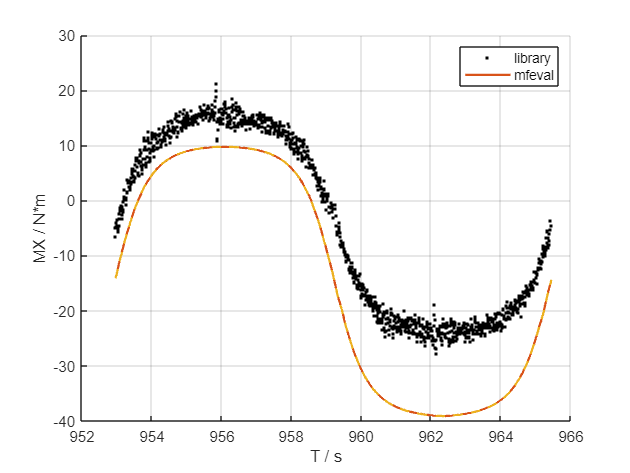

MX_mfeval = outMF(:,4);

r2d = @rad2deg;
figure(); hold on; grid on
plot(T, MX, 'k.')
plot(T, MX_mdl, 'LineWidth', 1.5)
plot(T, MX_mfeval, '--', 'LineWidth', 1.5)
legend library mfeval
ylabel('MX / N*m'); xlabel('T / s')